close all;clear;clc;

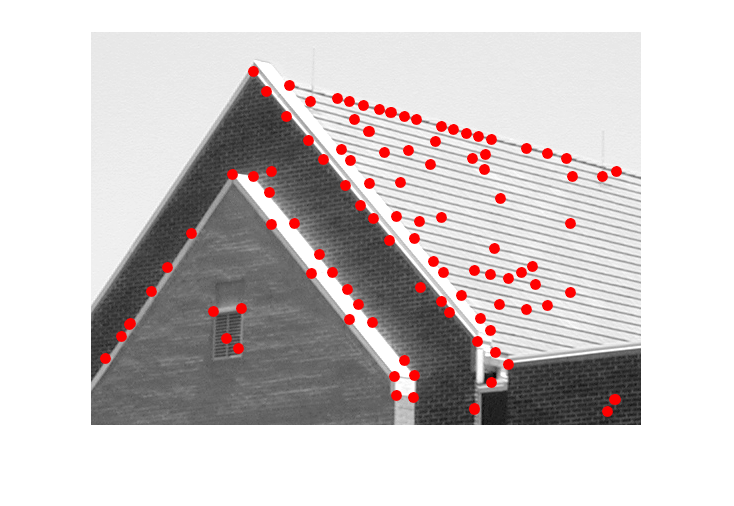

% Moravec角点检测函数的测试代码
I = imread('house.tif');
I = rgb2gray(I);
I = double(I);
counts = myMoravec(I,2,10,0.15);

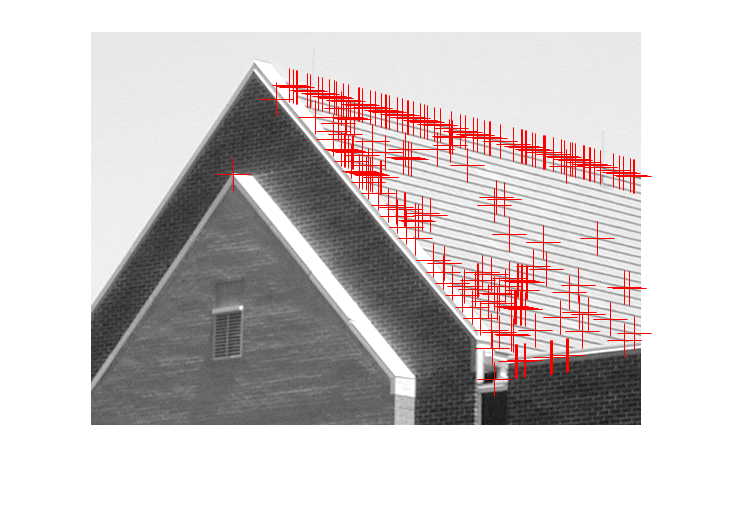

% SUSAN角点检测函数的测试代码
I = imread('house.tif');
I = rgb2gray(I);
I = double(I);
counts = mySusan(I,80,5);

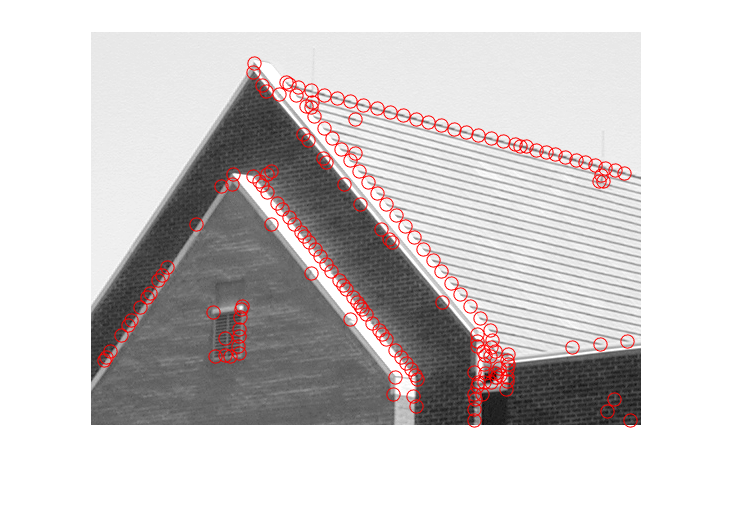

% Harris角点检测函数的测试代码
I = imread('house.tif');
if size(I,3) == 3
    I = rgb2gray(I);
end
I = double(I);
counts = myHarris(I,0.04,0.01);

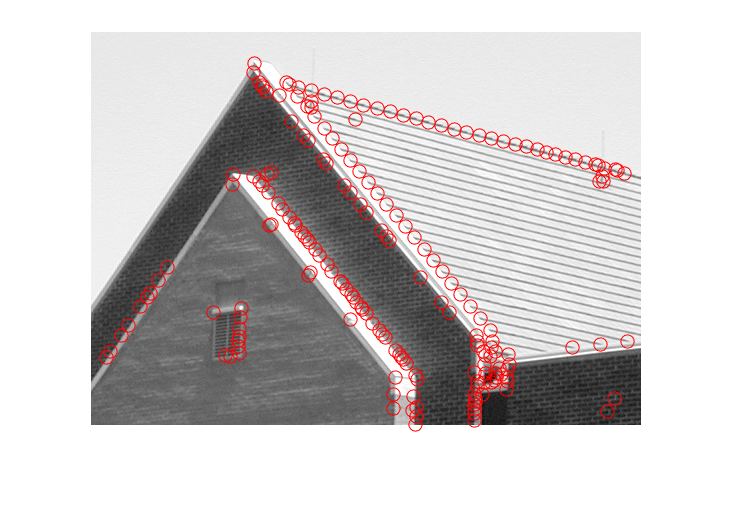

% 和matlab自带的Harris方法进行比较
I = imread('house.tif');
if size(I,3) == 3
    I = rgb2gray(I);
end
I = double(I);
tic;
C = corner(I);
imshow(I,[]);hold on;
plot(C(:,1),C(:,2),'ro','MarkerSize',8);

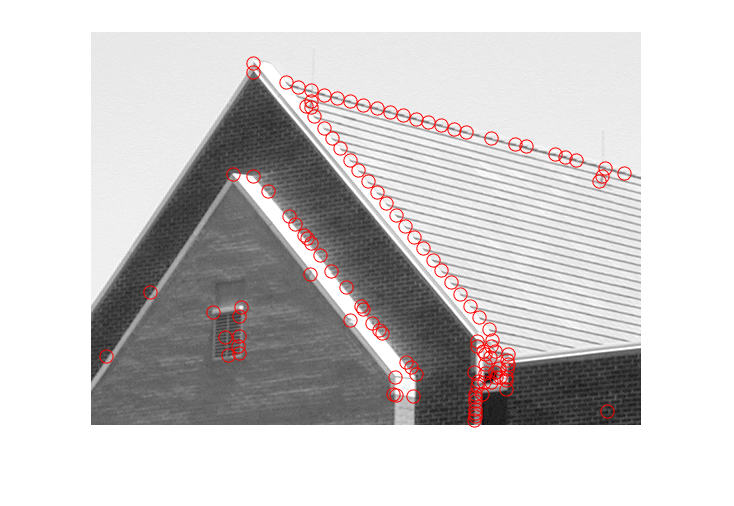

% Shi-Tomasi角点检测函数的测试代码
I = imread('house.tif');
if size(I,3) == 3
    I = rgb2gray(I);
end
I = double(I);
counts = myShiTomasi(I,0.1);

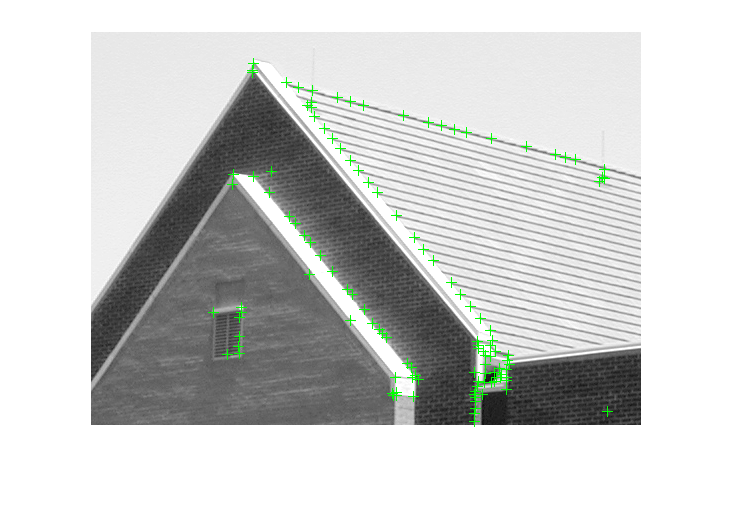

% 和matlab自带的Shi-Tomasi方法进行比较
I = imread('house.tif');
if size(I,3) == 3
    I = rgb2gray(I);
end
corners = detectMinEigenFeatures(I);
imshow(I,[]); hold on;
plot(corners.selectStrongest(120));

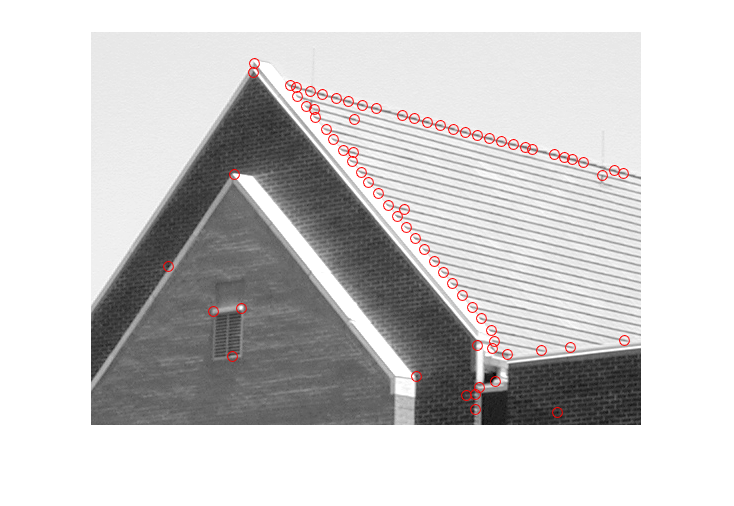

% Fast角点检测函数的测试代码
I = imread('house.tif');
if size(I,3) == 3
    I = rgb2gray(I);
end
I = double(I);
[x,y,corners] = myFast(I,35,11);

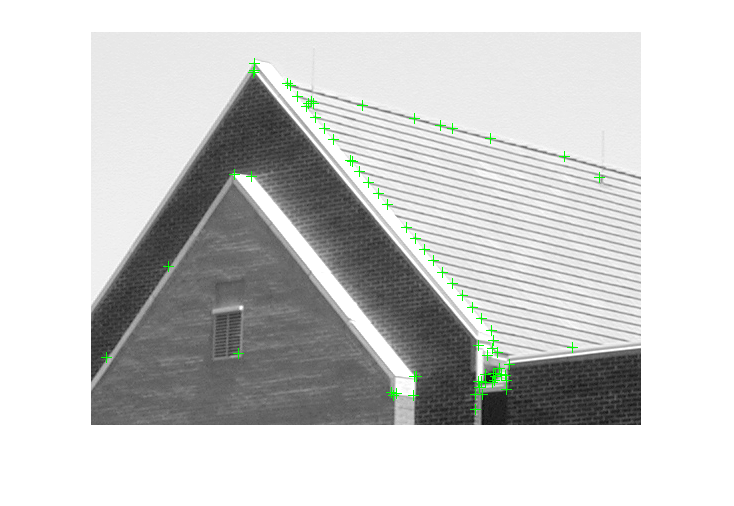

% 和matlab自带的Fast方法进行比较
I = imread('house.tif');
if size(I,3) == 3
    I = rgb2gray(I);
end
corners = detectFASTFeatures(I);
imshow(I,[]); hold on;
plot(corners.selectStrongest(100));